# Metodi iterativi per la risoluzione di sistemi lineari

Vogliamo risolvere un sistema lineare del tipo $Ax=b$ mediante il metodo di Jacobi.

## Introduzione

Scegliamo come matrice dei coefficienti$A = B^TB\in\mathbb{R}^{n\times n}$ , dove B è una matrice random di dimensione $n$

clc;
clear;
n = 80;
B = distributed(rand(n,n));
A = distributed(transpose(B)*B);
fprintf("Ordine matrice A: %u \n",n);

Ordine matrice A: 6400 


Scegliamo come vettore-colonna dei termini noti $b \in \mathbb{R}^N$


$$b = \sum_ {A_{i} \in J} A_{i}$$


dove $J = \{A_{1}, A_{2}, ..., A_{N}\}$denota l'insieme delle colonne della matrice $A$.

b = sum(A,2);

È possibile dimostrare che la soluzione del sistema $x_\text{exact} \in \mathbb{R}^n$ sia pari a


$$x_\text{exact} = [1, 1, ...,1]^T$$


xExact = ones(n,1,'distributed');

## Metodo di Jacobi con parametri di default

Come primo tentativo, risolviamo il sistema con il metodo di Jacobi, un metodo per la risoluzione di sistemi lineari che ad ogni passo genera una serie di soluzioni approssimate per $x_\text{exact}$.

La funzione pjm appartenente al Parallel Jacobi Method Toolbox fornisce un'implementazione parallela del metodo di Jacobi, che restituisce in output una lista di parametri tra cui figurano

- `xJM:` la soluzione approssimata per il sistema $Ax=b$;

- `flagJM`: un flag booleano indicante se il metodo di Jacobi converge, secondo la tolleranza desiderata;

- `resvecJM`: un vettore in cui ciascun elemento corrisponde al residuo normalizzato al termine di ogni iterazione, calcolato come  $$ \frac{|| b-Ax ||}{ || b ||}$$.  Si tratta di una metrica indicante l'accuratezza della soluzione calcolata tra un'iterazione e la successiva.

Inoltre, il criterio di arresto del metodo dipende da due ulteriori parametri: `maxit`, il numero massimo di iterazioni, e `tolerance` rappresentante l'accuratezza della soluzione trovata al termine dell'algoritmo. Nel caso in esame,

`tolerance` = $10^{-6}$

`maxit` = $\min \{100;n\}=100$

[xJM_1,flagJM_1,relresJM_1,iterJM_1,resvecJM_1] = pjm(A,b);

Procediamo con il calcolo dell'errore assoluto `errCG` tra le componenti corrispondenti di $x_\text{exact}$ ed `xCG.`

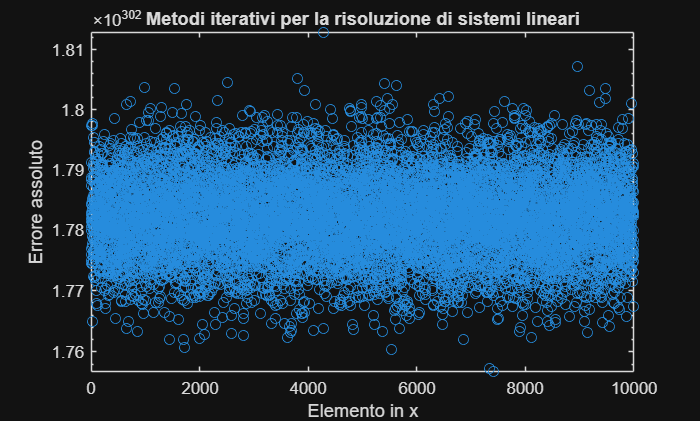

errJM_1 = abs(xExact - xJM_1);

figure(1)
semilogy(errJM_1,'o');
title('Metodi iterativi per la risoluzione di sistemi lineari');
ylabel('Errore assoluto');
xlabel('Elemento in x');

Notiamo che l'errore assoluto è elevato; infatti, il metodo di Jacobi non converge nel caso in esame a partire dal numero di iterazioni a disposizione. 

flagJM_1

flagJM_1 = 2

## Metodo di Jacobi con parametri personalizzati

Come secondo tentativo, modifichiamo i valori relativi ai parametri `maxit` e `tolerance`, con l'obiettivo di aumentare la probabilità che l'algoritmo converga. In particolare, impostiamo `tolerance` pari a $10^{-14}$ e forziamo il numero di iterazioni pari a $10000$.

tolerance = 1e-14;
maxit = 10000;      

tJM = tic;
[xJM_2,flagJM_2,relresJM_2,iterJM_2,resvecJM_2] = pjm(A,b,tolerance,maxit);
tJM = toc(tJM);

In questa configurazione personalizzata, il metodo di Jacobi converge.

flagJM_2

Complessivamente, l'errore assoluto risulta diminuito rispetto al tentativo precedente.

errCG_2 = abs(xExact - xCG_2);

figure(2)
semilogy(errCG_1,'o');
hold on
semilogy(errCG_2,'diamond');
title("Confronto dell'errore assoluto");
ylabel('Errore assoluto');
xlabel('Elemento in x');
legend('Metodo CG default','Metodo CG personalizzato');
hold off

Procediamo con il calcolo dei residui relativi alla prima iterazione per individuare il motivo per cui il metodo del gradiente coniugato è risultato non convergente al primo tentativo.

relresvecCG = resvecCG_2./resvecCG_2(1);

Dal grafico in figura, notiamo come sia impossibile raggiungere una soluzione sufficientemente approssimata per il sistema in questione con il numero di iterazioni di default.

px = 20;
py = relresvecCG(px);

figure(3)
f=semilogy(relresvecCG);
hold on
semilogy(f.Parent.XLim,[1e-6 1e-6],'--')
semilogy([20 20], f.Parent.YLim,'--')
semilogy(f.Parent.XLim,[1e-12 1e-12],'--')
plot(px,py, '-s')
title('Evoluzione dei residui relativi');
ylabel('Residuo relativo');
xlabel('Iterazione');
legend('Residue CG','Tolleranza di default','Numero iterazioni di default','Tolleranza personalizzata')
hold of
